Vine Robot Modeling

Lets start with a simple 3D case

Let try it with real numbers

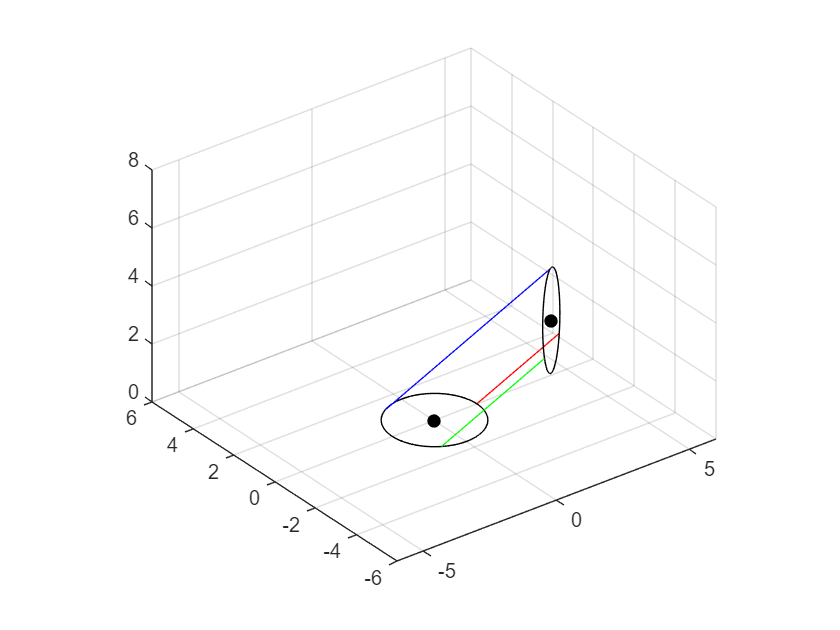

%Credit to https://doi.org/10.1038/s41467-024-54327-6 for the modeling
%walkthrough


%Define lengths of each actuator
L_k1 = 4;
L_k2 = 5;
L_k3 = 8;
r = 5*2/pi/2; %From my actual vine robot


%Might need to define phi_kj
phi_kj = 0;

%Length matrix
L_k = [L_k1 L_k2 L_k3]';

%Length of center
L_ck = (L_k1+L_k2+L_k3)/3;

%One angle
beta_k = 2*sqrt(L_k1^2+L_k2^2+L_k3^2-L_k1*L_k2-L_k1*L_k3-L_k2*L_k3)/(3*r);
%Another angle - see paper
theta_k = atan2(3*(L_k2-L_k3),sqrt(3)*(L_k2+L_k3-2*L_k1));

Q_k = [L_ck theta_k beta_k]';

delta_kj = r*cos(phi_kj-theta_k);

%How to calculate the length of each actuator
L_kj = L_ck-delta_kj*beta_k;

rho_k = beta_k/L_ck;

R_k = [cos(beta_k)*cos(theta_k)^2 + sin(theta_k)^2 (-1+cos(beta_k))*cos(theta_k)*sin(theta_k) cos(theta_k)*sin(beta_k)
       (-1+cos(beta_k))*cos(theta_k)*sin(theta_k) cos(theta_k)^2+cos(beta_k)*(sin(theta_k))^2 sin(theta_k)*sin(beta_k)
       -cos(theta_k)*sin(beta_k) -sin(beta_k)*sin(theta_k) cos(beta_k)];

%This does not work when all lengths are equal
P_k = 1/rho_k*[(1-cos(beta_k))*cos(theta_k) (1-cos(beta_k))*sin(theta_k) sin(beta_k)]';
T_k = [R_k P_k
        0 0 0 1];

%Seems to be working alright, lets plot it
Base_coord = [1 0 0 0
              0 1 0 0
              0 0 1 0
              0 0 0 1];
New_coord = Base_coord*T_k;
Old_xyz = [Base_coord(1,4),Base_coord(2,4),Base_coord(3,4)]';
New_xyz = [New_coord(1,4),New_coord(2,4),New_coord(3,4)]';

plot3(Old_xyz(1),Old_xyz(2),Old_xyz(3),'.','MarkerSize',20,'Color','black')
axis equal
grid on
xlim([-6 6])
ylim([-6 6])
zlim([0 8])
hold on
plot3(New_xyz(1),New_xyz(2),New_xyz(3),'.','Markersize',20,'Color','black')

%Plot arc from center
%arc(New_xyz',Old_xyz',rho_k,'black')
%Find actuator position because it looks cool
act_1_start = [r 0 0 1]';
act_2_start = [r*cos(2*pi/3) r*sin(2*pi/3) 0 1]';
act_3_start = [r*cos(4*pi/3) r*sin(4*pi/3) 0 1]';
act_1_end = T_k*act_1_start;
act_2_end = T_k*act_2_start;
act_3_end = T_k*act_3_start;
act_1_old = [act_1_start(1),act_1_start(2),act_1_start(3)]';
act_1_new = [act_1_end(1),act_1_end(2),act_1_end(3)]';
act_1_phi = beta_k/L_k1;
%arc(act_1_new',act_1_old',act_1_phi,'red')

act_2_old = [act_2_start(1),act_2_start(2),act_2_start(3)]';
act_2_new = [act_2_end(1),act_2_end(2),act_2_end(3)]';
act_2_phi = beta_k/L_k2;
%arc(act_2_new',act_2_old',act_2_phi,'green')

act_3_old = [act_3_start(1),act_3_start(2),act_3_start(3)]';
act_3_new = [act_3_end(1),act_3_end(2),act_3_end(3)]';
act_3_phi = beta_k/L_k3;
%arc(act_3_new',act_3_old',act_3_phi,'blue')
circle(act_1_old',act_2_old',act_3_old','black')
circle(act_1_new',act_2_new',act_3_new','black')

%For now I am commenting out the arc drawings as they do not work
plot3([act_1_old(1) act_1_new(1)],[act_1_old(2) act_1_new(2)],[act_1_old(3) act_1_new(3)],'Color','red')
plot3([act_2_old(1) act_2_new(1)],[act_2_old(2) act_2_new(2)],[act_2_old(3) act_2_new(3)],'Color','blue')
plot3([act_3_old(1) act_3_new(1)],[act_3_old(2) act_3_new(2)],[act_3_old(3) act_3_new(3)],'Color','green')


angle = acos((trace(R_k)-1)/2)*180/pi

angle = 86.5332


length1 = norm(act_1_old-act_1_new)

length1 = 3.6305


length2 = norm(act_2_old-act_2_new)

length2 = 7.2611

length3 = norm(act_3_old-act_3_new)

length3 = 4.5382















%Functions that I modified from chatGPT to help with visualization



%Function that plots an arc based on end points and curvature. This does
%not work as intended as there are 2 possible arc positions
function arc(p1,p2,kappa,color)
      % Curvature (positive = left turning)
    % Calculate radius
    R = 1 / abs(kappa);
    % Vector from p1 to p2
    chord = p2 - p1;
    L = norm(chord);
    midpoint = (p1 + p2) / 2;
    % Normal to the plane: if not provided, choose a default
    % You can define a plane normal (e.g., z-axis), or use an auxiliary point
    % For simplicity, we'll define it to be perpendicular to chord in Z-up space
    if all(cross(chord, [0 0 1]) == 0)
        plane_normal = [0 1 0];  % Avoid degenerate case
    else
        plane_normal = cross(chord, [0 1 0]);
    end
    plane_normal = plane_normal / norm(plane_normal);
    % Perpendicular direction within plane
    dir = chord / L;
    perp = cross(plane_normal, dir);
    perp = perp / norm(perp);
    % Distance from midpoint to center
    h = sqrt(R^2 - (L/2)^2);
    center = midpoint + sign(kappa) * h * perp;
    % Compute arc angle range
    v1 = p1 - center;
    v2 = p2 - center;
    theta1 = 0;
    theta2 = acos(dot(v1, v2) / (norm(v1) * norm(v2)));
    % Ensure direction of arc matches curvature
    if dot(cross(v1, v2), plane_normal) < 0
        theta2 = -theta2;
    end
    % Create arc
    N = 100;
    theta = linspace(theta1, theta2, N);
    arc = zeros(N, 3);
    v1_norm = v1 / norm(v1);
    for i = 1:N
        rot_axis = plane_normal;
        angle = theta(i);
        rot_axis = rot_axis / norm(rot_axis);
        v_rot = v1_norm*cos(angle) + cross(rot_axis, v1_norm)*sin(angle) + rot_axis*dot(rot_axis,v1_norm)*(1 - cos(angle));
        arc(i, :) = center + v_rot * R;
    end
    % Plot
    plot3(arc(:,1), arc(:,2), arc(:,3),'-','Color',color);
end

%Function for drawing a circle from 3 points
function circle(P1,P2,P3,color)
    % Step 1: Calculate vectors for the sides of the triangle
    v12 = P2 - P1;
    v13 = P3 - P1;
    % Step 2: Compute the normal vector to the plane
    normal = cross(v12, v13);
    normal = normal / norm(normal);  % Normalize
    % Step 3: Compute the midpoints of the sides
    mid12 = (P1 + P2) / 2;
    mid13 = (P1 + P3) / 2;
    % Step 4: Find the direction vectors of the perpendicular bisectors
    perp12 = cross(normal, v12);
    perp13 = cross(normal, v13);
    % Step 5: Find the intersection of the perpendicular bisectors (circumcenter)
    % Parametrize the perpendicular bisectors to find their intersection
    % Line 1: mid12 + t1 * perp12
    % Line 2: mid13 + t2 * perp13
    A = [perp12; -perp13]';  % Coefficients for the system of equations
    b = mid13 - mid12;       % The difference vector
    % Solve the system of linear equations to find t1 and t2
    t = A \ b';
    % Find the circumcenter (intersection point)
    circumcenter = mid12 + t(1) * perp12;
    % Step 6: Calculate the radius (distance from circumcenter to any point)
    radius = norm(circumcenter - P1);
    % Step 7: Parametrize the circle
    theta = linspace(0, 2*pi, 200);  % Parameter for the circle
    u = v12 / norm(v12);             % First direction in the plane
    v = cross(normal, u);            % Second direction in the plane
    v = v / norm(v);                 % Normalize to make orthonormal
    % Circle points
    circle3D = circumcenter' + radius * (u' * cos(theta) + v' * sin(theta));   
    % Plot
    plot3(circle3D(1,:), circle3D(2,:), circle3D(3,:), '-','Color',color);
end